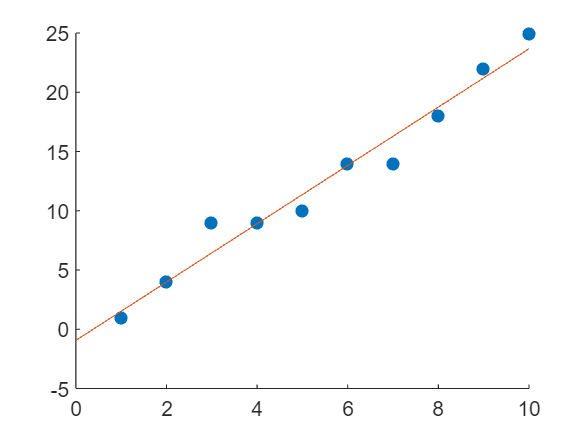

% Need some points 
xi = [1,2,3,4,5,6,7,8,9,10];
yi = [1,4,9,9,10,14,14,18,22,25];

% plot points
figure;
hold on;
scatter(xi, yi,'filled');
hold off;

% Calculate 2x2 matrix entries
A = zeros(2,2);
b = [0,0]';
s = size(xi);
n = s(2);

sum_xi = 0;
sum_xi_squared = 0;
sum_yi = 0;
sum_xi_yi = 0;
for i = 1:n
    sum_xi = sum_xi + xi(i);
    sum_xi_squared = sum_xi_squared + xi(i)^2;
    sum_yi = sum_yi + yi(i);
    sum_xi_yi = sum_xi_yi + xi(i)*yi(i);
end


% Fill in the matrices
A(1,1) = n;
A(1,2) = sum_xi;
A(2,1) = sum_xi;
A(2,2) = sum_xi_squared;
b(1) = sum_yi;
b(2) = sum_xi_yi;

% Solve the equation

x = linsolve(A,b);

% Graph the result: y = ao + a1x

x_vals = linspace(0,xi(end),100);
y_vals = x(1) + x_vals*x(2);

% plot alongside the original points
hold on;
plot(x_vals, y_vals)


% Calculate error
a0 = x(1);
a1 = x(2);
Sr = 0;
St = 0;
y_avg = sum_yi/n;
for i = 1:n
    Sr = Sr + (yi(i) - a0 - a1*xi(i))^2;
    St = St + (yi(i) - y_avg)^2;
end
r = sqrt((St-Sr)/St)

r = 0.9835